# **Procesamiento de Imagenes Digitales**

# **Taller 4**

## **Cargar imagen**

Cargue la imagen "moon.tif" y visualicela en la figure(1).

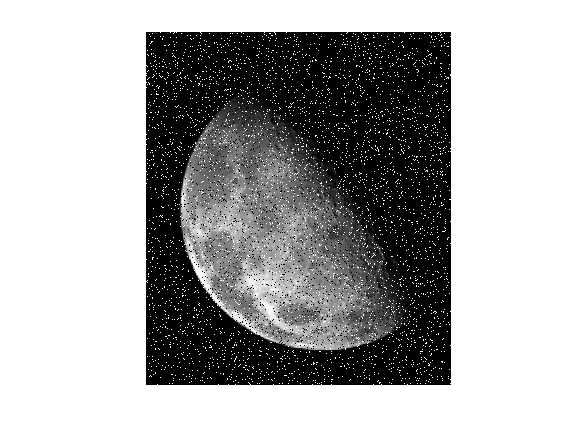

I = imread('moon.tif');
figure(1);imshow(I);

## Limpiar imagen

Seguramente después de observar la imagen pueda percibir alguna clase de ruido que afecta su visualización. Aplique el filtro (3x3) que considere apropiado para limpiarla y reducir el efecto nocivo del ruido. Visualice la imagen filtrada en figure(2). 

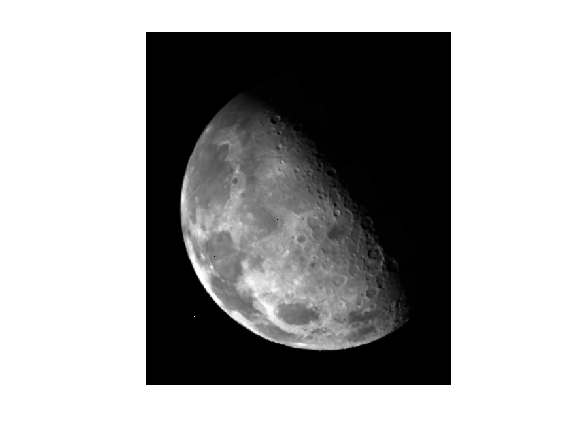

Imed = medfilt2(I,[3 3],'symmetric');
figure(2);imshow(Imed);

¿Está totalmente limpia la imagen? ¿Con que filtro podría limpiar y dar un boco de efecto "blurred" caracteristico de la luna a la imagen, justifique? Visualice la imagen post procesada en figure(3).

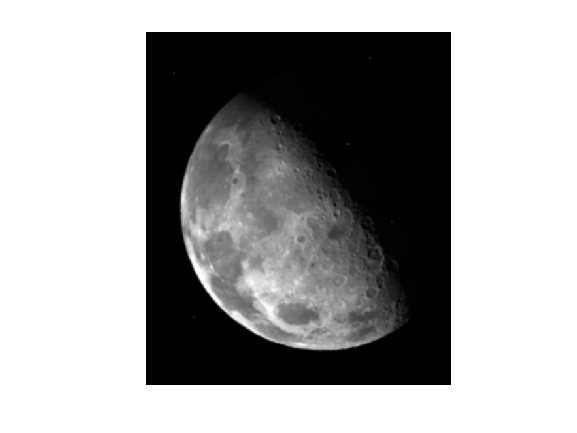

k1 = ones(3,3)/9;
I1 = imfilter(Imed,k1);
figure(3);imshow(I1);

Dando un filtro de suavisado de la media a la imagen que se le aplico un filtro de la mediana da como resultado un efecto blurred en la imagen.

## Reducir información irrelevante

Es probable que logre percibir algunos puntos fuera del objeto de estudio, que no son de interés en la imagen. ¿Con que filtro logra reducir esa pequeña contaminación en la imagen? Visualice en figure(4) y justifique.

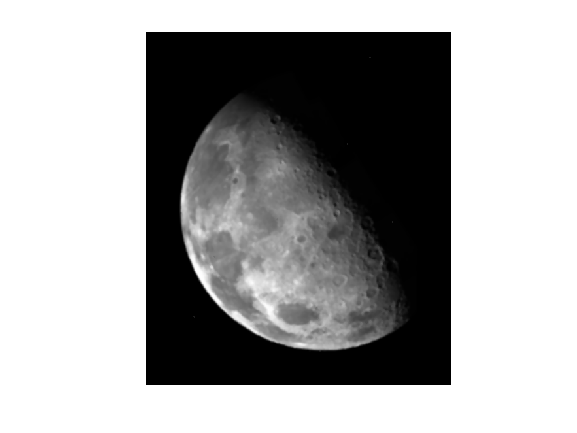

Imed2 = medfilt2(I1,[3 3],'symmetric');
figure(4);imshow(Imed2);

Si volvemos a aplicar el filtro de la mediana 3x3 a la imagen con limpiada, podemos quitar el ruido faltante de la imagen a la cual se le hizo una limpieza.

## Detectar el borde de la Luna

Aplique un kernel Laplaciano 3x3 y su negativo, visualice las imágenes filtradas en figure(5) y figure(6). ¿Cuál kernel resulta más apropiado para está imagen? 

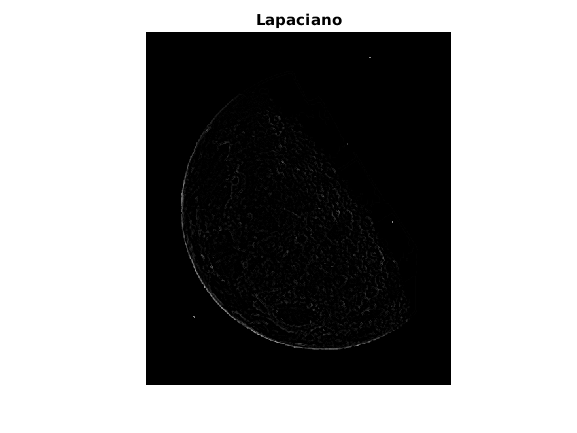

l = [ -1 -1 -1 ;...
    -1  8 -1 ;...
    -1 -1 -1 ;...
    ];

Ilap = imfilter(Imed2,l);
IlapN = imfilter(Imed2,-l);
figure(5);imshow(Ilap);title('Lapaciano');

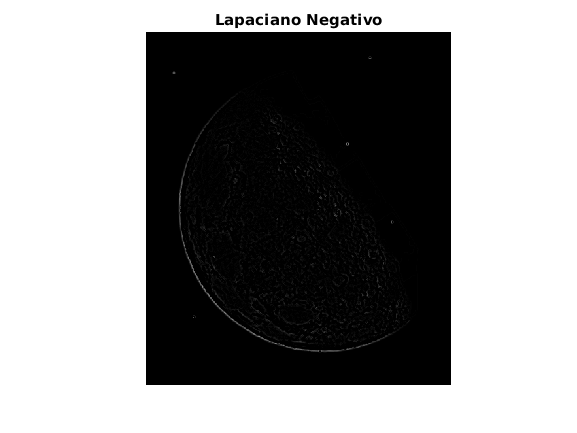

imshow(IlapN);title('Lapaciano Negativo');

El lapaciano comvencional resulta mas eficiente para identificar los bordes de la imagen, ya que se pueden detallar mucho mejor los bordes en general.

## El negativo de la imagen

Calcule el negativo de la imagen y visualice en figure(7).

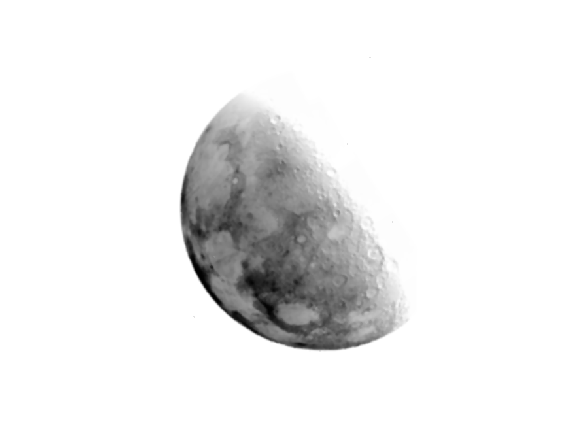

Ineg = imadjust(Imed2, [0 1], [1 0]);
figure(7);imshow(Ineg);

Aplique un kernel Laplaciano 3x3 y su negativo, visualice las imágenes filtradas en figure(8) y figure(9). ¿Cuál kernel resulta más apropiado para está imagen? 

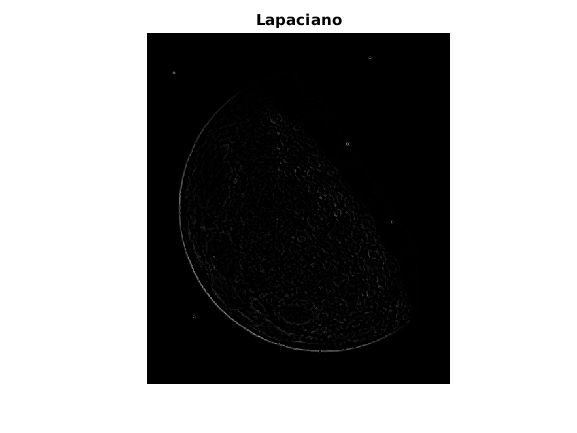

InegLap = imfilter(Ineg,l);
InegLapN = imfilter(Ineg,-l);
figure(8);imshow(InegLap);title('Lapaciano');

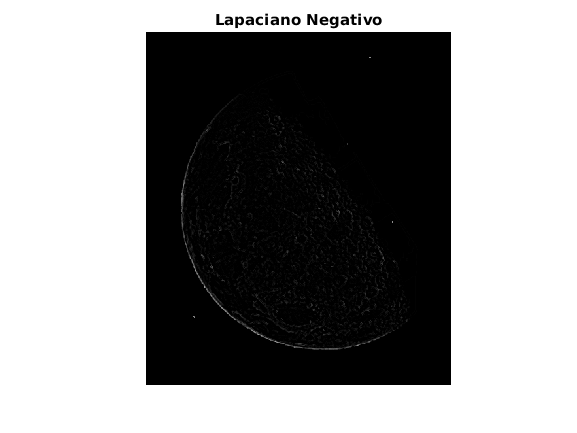

figure(9);imshow(InegLapN);title('Lapaciano Negativo');

Al hallar el lapaciano al negativo de la imagen cambia las carracteristicas de los bordes y por tanto hace que el lapaciano negativo resulte mas eficiente para distingir los bordes de la imagen.